Step 1: Load and Visualize EEG Data

This script loads raw EEG data from the PhysioNet Motor Imagery 

dataset and visualizes the brain signals using EEGLAB.

% Clear workspace
%clear; close all; clc;
% Set base path
basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';
% Load one subject EEG file using EEGLAB
EEG = pop_biosig(fullfile(basePath, 'Data', 'S001R03.edf'));

sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in EDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Extracting events from last EEG channel...
         To extract events, use menu File > Import Event Info > From data channel
eeg_checkset warning: 1/30 events had out-of-bounds latencies and were removed
eeg_checkset note: creating the original event table (EEG.urevent)


% Print basic info
disp(['Number of channels: ', num2str(EEG.nbchan)]);

Number of channels: 64


disp(['Sampling rate: ', num2str(EEG.srate), ' Hz']);

Sampling rate: 160 Hz


disp(['Total time points: ', num2str(EEG.pnts)]);

Total time points: 20000


disp(['Duration: ', num2str(EEG.pnts/EEG.srate), ' seconds']);

Duration: 125 seconds


**visualize the raw EEG signals.**

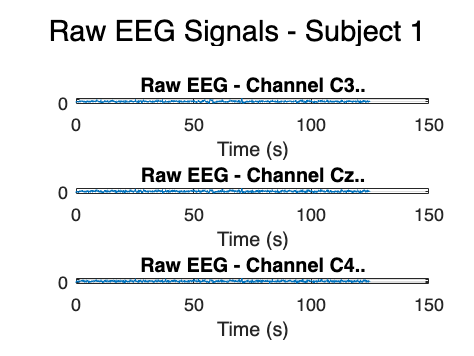

% Plot raw EEG signals
figure;
for i = 1:length(ch_idx)
    subplot(3,1,i);
    plot(EEG.times/1000, EEG.data(ch_idx(i),:));
    title(['Raw EEG - Channel ', channels{i}]);
    xlabel('Time (s)');
    ylabel('Amplitude (\muV)');
    grid on;
end
sgtitle('Raw EEG Signals - Subject 1');

% Save plot
saveas(gcf, fullfile(basePath, 'Outputs', 'Plots', 'raw_eeg.png'));

disp('Plot saved!');

Plot saved!


Step 2: Filter the EEG Signal (8-30 Hz)% Raw EEG contains noise — we keep only motor imagery frequencies

%Apply band-pass filter using EEGLAB
EEG_filtered = pop_eegfiltnew(EEG, 8, 30);

pop_eegfiltnew() - performing 265 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [8 30] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [7 31] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


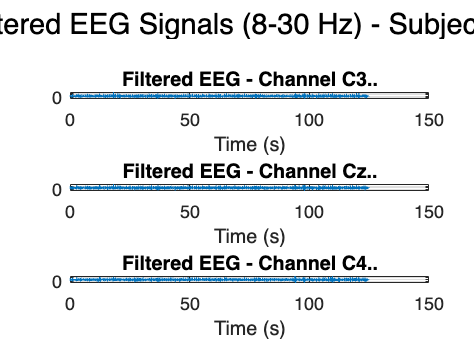


% Plot filtered signals
figure;
for i = 1:length(ch_idx)
    subplot(3,1,i);
    plot(EEG_filtered.times/1000, EEG_filtered.data(ch_idx(i),:));
    title(['Filtered EEG - Channel ', channels{i}]);
    xlabel('Time (s)');
    ylabel('Amplitude (\muV)');
    grid on;
end
sgtitle('Filtered EEG Signals (8-30 Hz) - Subject 1');

% Save plot
saveas(gcf, fullfile(basePath, 'Outputs', 'Plots', 'filtered_eeg.png'));

disp('Filtered plot saved!');

Filtered plot saved!


% Save the filtered EEG for next steps

EEG_filtered = pop_saveset(EEG_filtered, ...
    'filename', 'S001R03_filtered.set', ...
    'filepath', fullfile(basePath, 'Outputs', 'Filtered data'));
disp('Filtered EEG saved!');